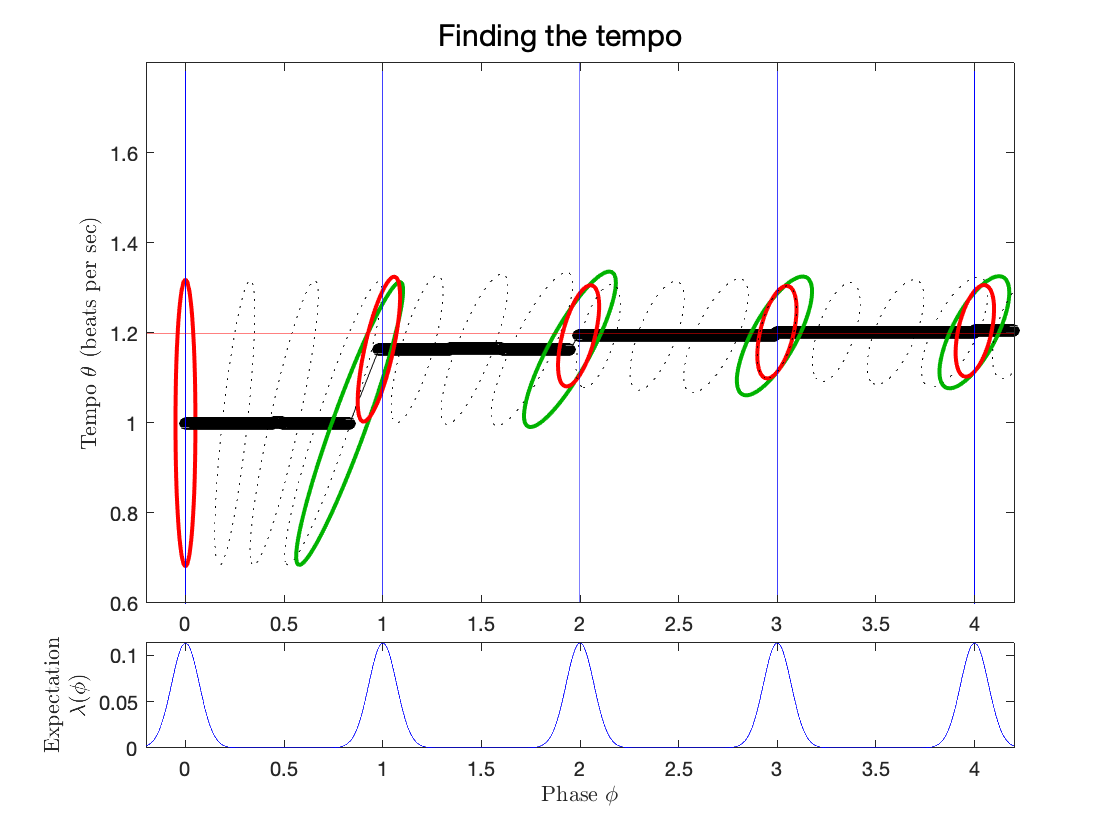

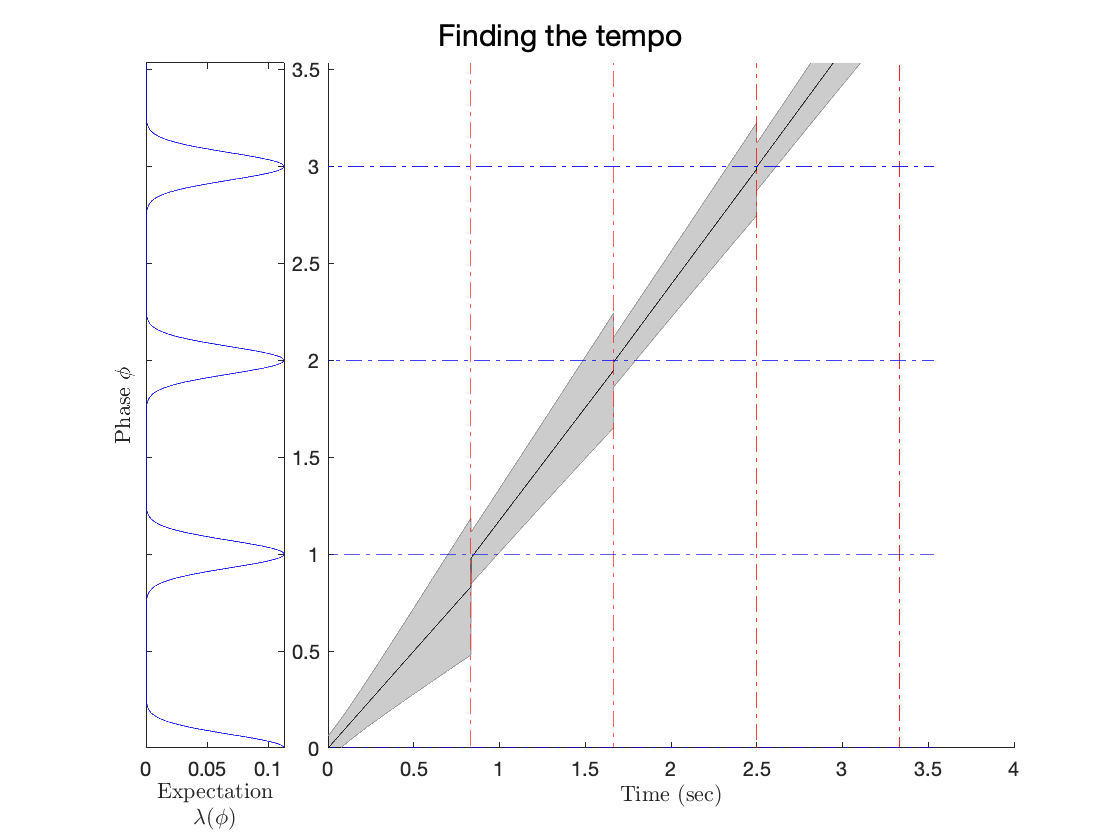

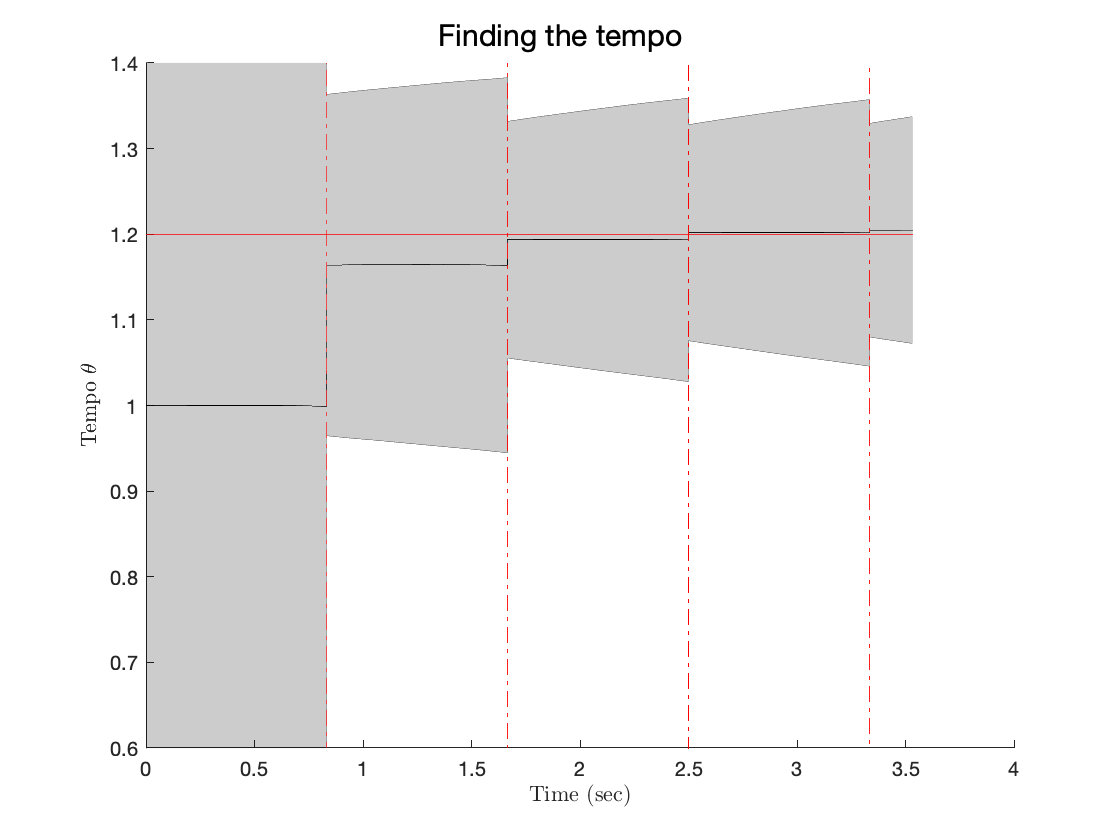


true_tempo = 1.2;
period = 1/true_tempo;

params = PATIPPET_params(...
    'means_unit', [0],...
    'variance_unit', [.005],...
    'expected_cycles', 5,...
    'expected_period', 1,...
    'true_speed', true_tempo,...
    'event_times', period:period:4*period,...%[.8, 1.6, 2.4, 3.2, 4.0],...
    'mu_0', [0,1],...
    'V_0', [.001,0; 0,.04],...
    'lambda_0', .0001,...
    'dt_ellipse',.25,...
    'title', 'Finding the tempo', ...
    'display_phase', true, ...
    'display_tempo', true);
[mu_list, V_list] = run_PATIPPET(params);

fig =   Figure (130) with properties:

      Number: 130
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [560 528 560 420]
       Units: 'pixels'

  Show all properties


i = 1

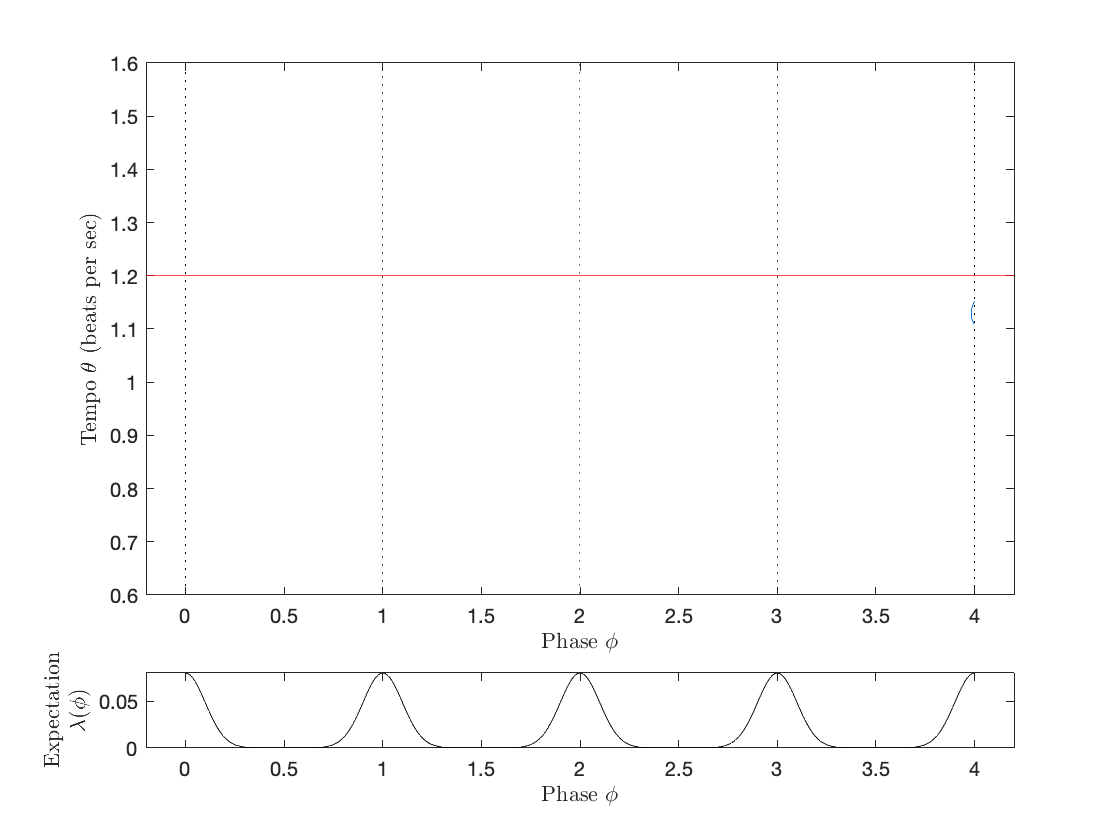

make_PATIPPET_video('PATIPPET_live', params, mu_list, V_list, [0,4], [.6:1.8], 'MPEG-4')

params = PATIPPET_params(...
    'means_unit', [1],...
    'expected_cycles', 4,...
    'expected_period', 1,...
    'true_speed', true_tempo,...
    'event_times', period:period:4*period,...%[.8, 1.6, 2.4, 3.2, 4.0],...
    'mu_0', [0,.8],...
    'V_0', [.001,0; 0,.04],...
    'lambda_0', .0001,...
    'dt_ellipse',.25,...
    'title', 'Finding the tempo', ...
    'display_phasetempo', false);
[mu_list, V_list] = run_PATIPPET(params);

params = PATIPPET_params(...
    'means_unit', [1],...
    'expected_cycles', 4,...
    'expected_period', 1,...
    'true_speed', true_tempo,...
    'event_times', period:period:4*period,...%[.8, 1.6, 2.4, 3.2, 4.0],...
    'mu_0', [0, 1],...
    'V_0', [.001,0; 0,0],...
    'sigma_theta', 0,...
    'lambda_0', .0001,...
    'dt_ellipse',.25,...
    'title', 'Finding the tempo', ...
    'display_phasetempo', false);
[mu_list_2, V_list_2] = run_PATIPPET(params);


figure()
plot(squeeze(sqrt(V_list(1,1,:))))
hold on
plot(squeeze(sqrt(V_list_2(1,1,:))))
ylabel('Phase uncertainty (ms)')
xlabel('t (ms)')



## Phase shift as a function of tempo

PATIPPET is given time to entrain to four different tempi, and then given a phase shifted click. Taps are assumed to happen each time the mean estimated phase reaches an integer, except at the phase shift, which is assumed to take place too close to a tap for that tap to adjust. Tap times are used to 


dt = .001;
V_list = .01%[0.01, 0.005, 0.05];

sigma_list = 0.0100

sigma_theta_list = .01%[0.01, 0.02, 0.002];

sigma_theta_list = 0.0100

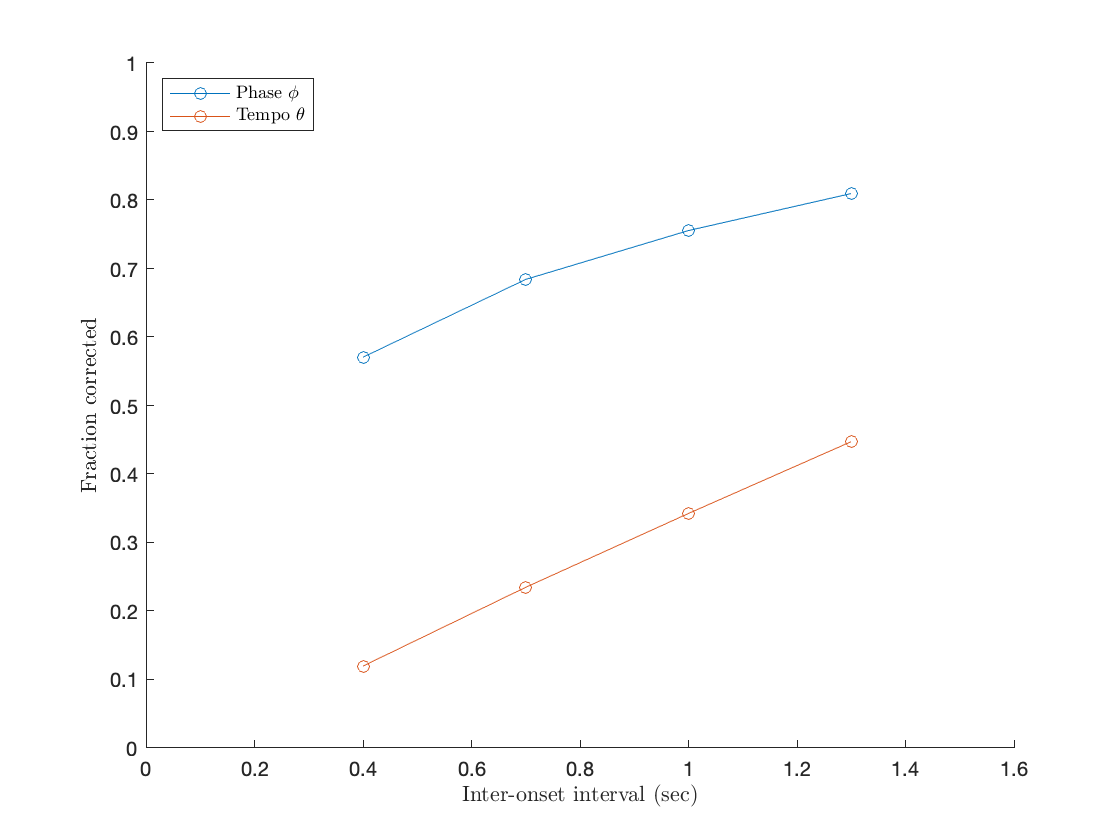

period_list = [.4, .7, 1, 1.3];
alpha_list = zeros(length(V_list), length(period_list));
for c=1:length(V_list)

params = PATIPPET_params(...
    'means_unit', [1],...
    'variance_unit', [.0002],...
    'expected_cycles', 4,...
    'expected_period', 1,...
    'sigma_phi', V_list(c),...
    'sigma_theta', sigma_theta_list(c),...
    'lambda_0', .00001,...
    'V_0', [.0001, 0; 0, .0001],...
    'dt_ellipse', .05,...
    'TDDM', false,...
    'display_phasetempo', true); %true


%%% Any of the following phase shift schemes give similar results.

%delta_list = -period_list.^2 / 20; % phase shifts corresponding to equal tempo changes
%delta_string = "\Delta = IOI^2 / 20";
delta_list = -period_list / 25; % phase shifts proportional to period
delta_string = "\Delta = IOI/25";
%delta_list = -.01*ones(size(period_list)); % identical phase shifts
%delta_string = "\Delta = 0.01 sec";


mu_final_list = zeros(2, length(period_list));
mu_initial_list = zeros(2, length(period_list));
V_final_list = zeros(2,2, length(period_list));
V_initial_list = zeros(2,2, length(period_list));

for i = 1:length(period_list)
    params.streams{1}.event_times = [period_list(i), 2*period_list(i), 3*period_list(i), 4*period_list(i)+delta_list(i)];
    params.tmax = 4*period_list(i)+delta_list(i);
    params.true_speed = 1/period_list(i);
    params.mu_0 = [0, 1/period_list(i)];
    params.title = "IOI = " + num2str(period_list(i))+ " sec, "+delta_string; % Correct title if using different
    
    [mu_list, V_list] = run_PATIPPET(params);
    ylim([1/period_list(i) - .15, 1/period_list(i)+.15])
    xlim([3.6, 4.2])
    plot([3.6, 4.2], [1,1]*(1./(period_list(i)+delta_list(i))));
    subplot(5,1,5)
    xlim([3.6, 4.2])
    mu_final_list(:, i) = mu_list(:, end);
    mu_initial_list(:, i) = mu_list(:, end-1);
    V_final_list(:,:, i) = V_list(:, :,end);
    V_initial_list(:,:, i) = V_list(:, :,end-1);
    
    i
end

fourth_tap_times = 4*period_list;

phase_until_next_tap = 5 - mu_final_list(1,:);

time_until_next_tap = phase_until_next_tap./mu_final_list(2,:);

fifth_tap_times = fourth_tap_times + delta_list + time_until_next_tap;

next_asynchrony = (5*period_list + delta_list) - fifth_tap_times;

alpha_list(c,:) = (delta_list-next_asynchrony)./delta_list;

figure()
hold on
plot(period_list, -(mu_final_list(1,:)-mu_initial_list(1,:))./(delta_list/period_list), 'o-')
plot(period_list, (mu_final_list(2,:) - mu_initial_list(2,:))./(1./(period_list + delta_list) - 1./period_list), 'o-')
%plot(period_list, mu_initial_list(1,:), 'o-')
ylabel('Fraction corrected','Interpreter','Latex')
xlabel('Inter-onset interval (sec)','Interpreter','Latex')
lgd = legend('Phase $\phi$', 'Tempo $\theta$','Interpreter','Latex');
lgd.Location = 'northwest';
xlim([0, 1.6])
ylim([0, 1])

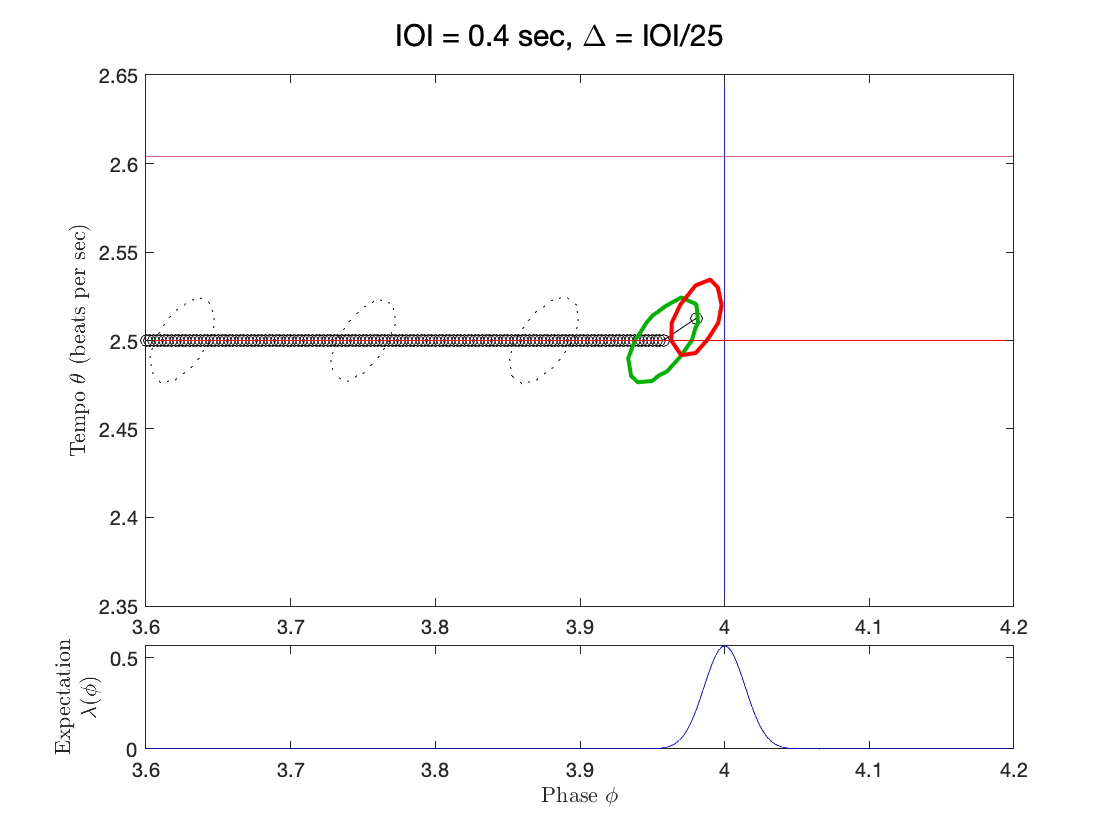

i = 1

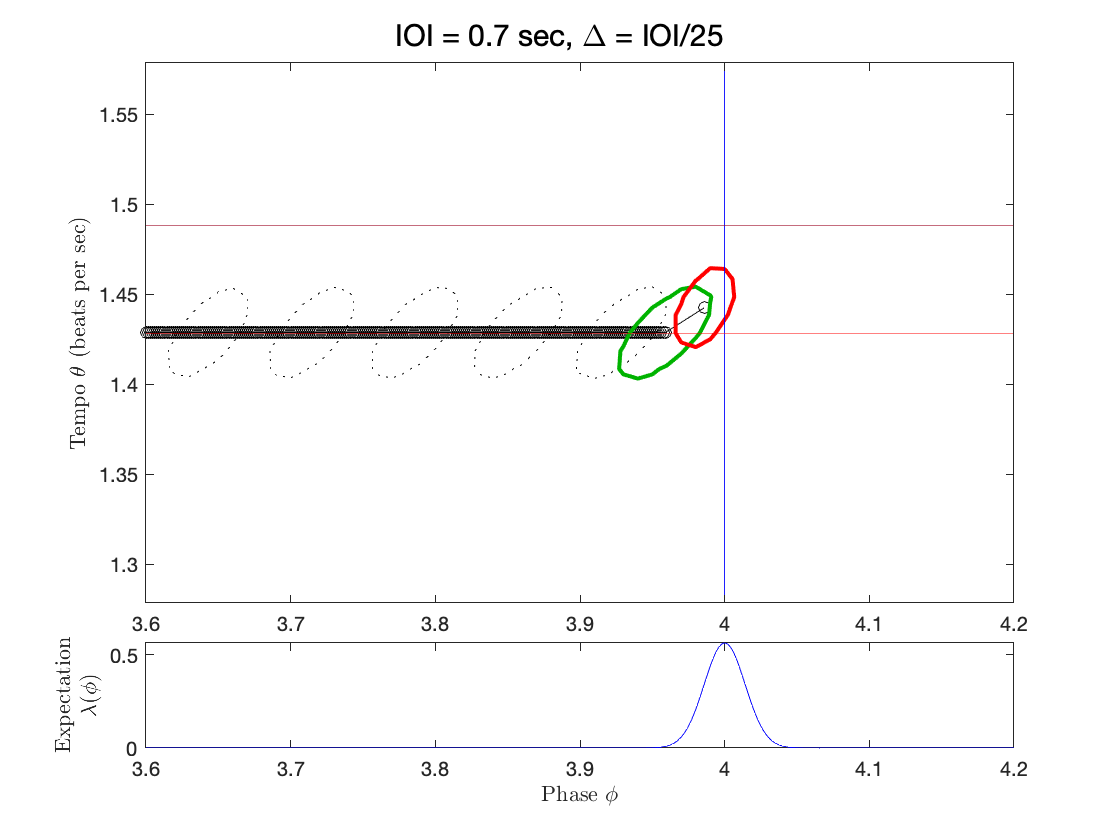

i = 2

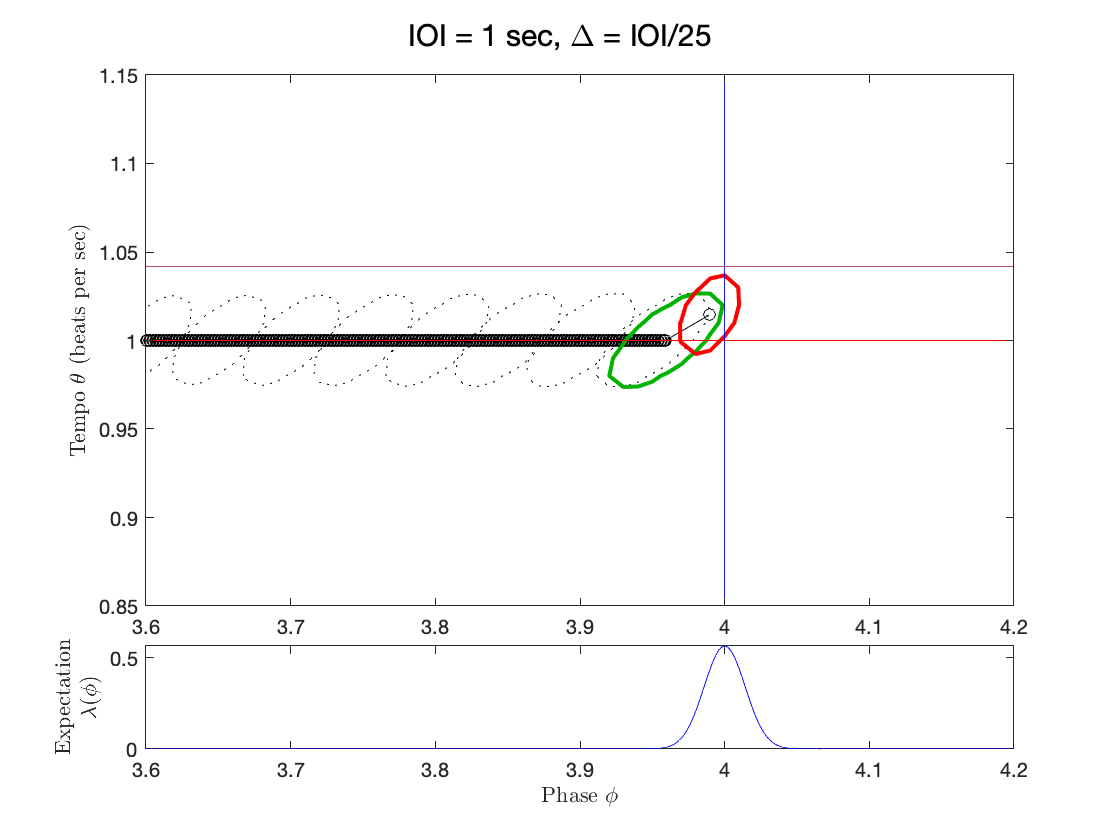

i = 3

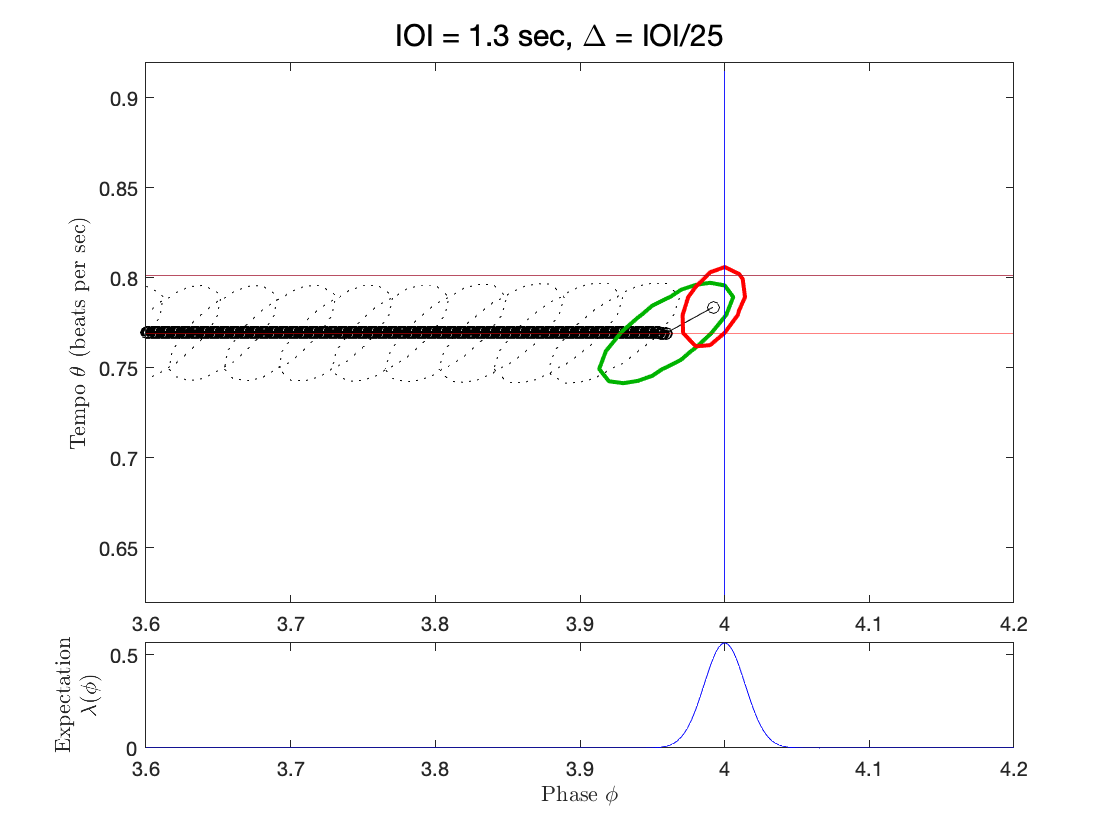

i = 4

%ylim([3.9, 4])

end

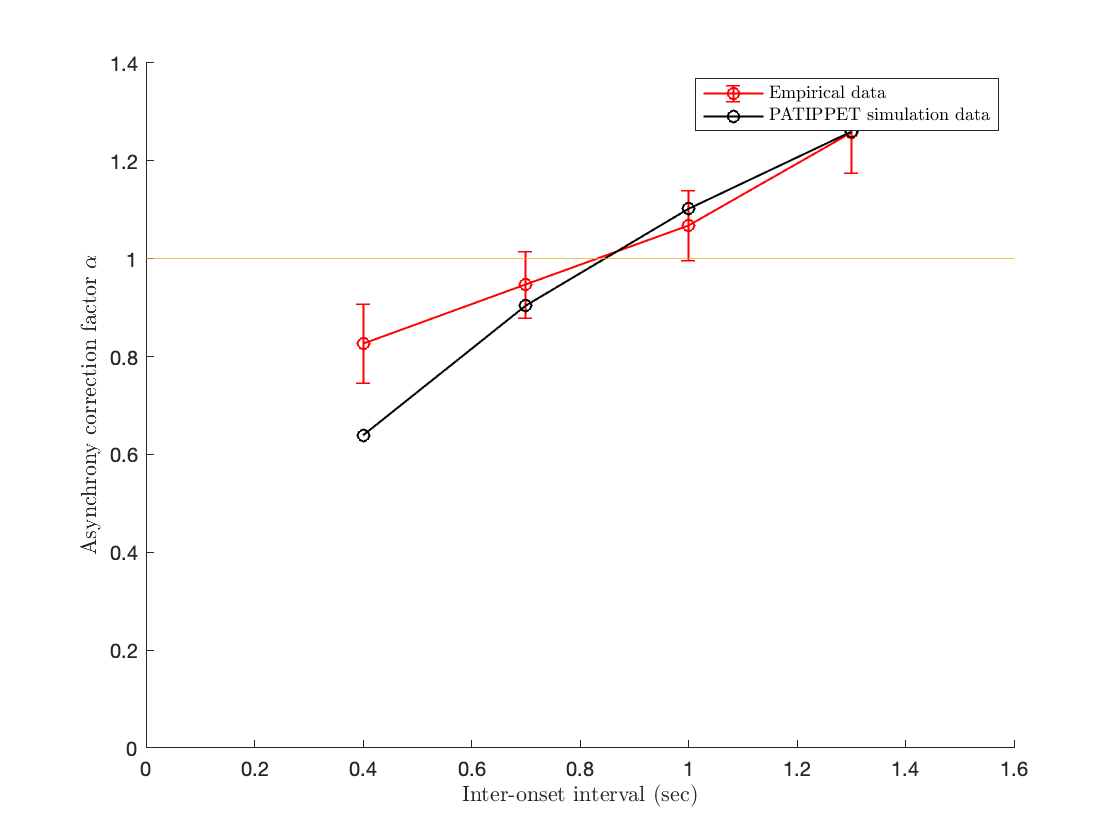

C = csvread('PS.csv');
figure()
hold on
errorbar(period_list, mean(C,1), std(C,1)/sqrt(size(C,1)), 'ro-', 'LineWidth', 1)
for c = 1:length(V_list)
plot(period_list, alpha_list(c,:), 'ko-', 'LineWidth', 1)
end

plot([0,1.6], [1,1], '-')
ylabel('Asynchrony correction factor $\alpha$','Interpreter','Latex')
xlabel('Inter-onset interval (sec)','Interpreter','Latex')
legend('Empirical data', 'PATIPPET simulation data', 'Interpreter','Latex')
xlim([0, 1.6])
ylim([0, 1.4])

## Exploring tempo changes

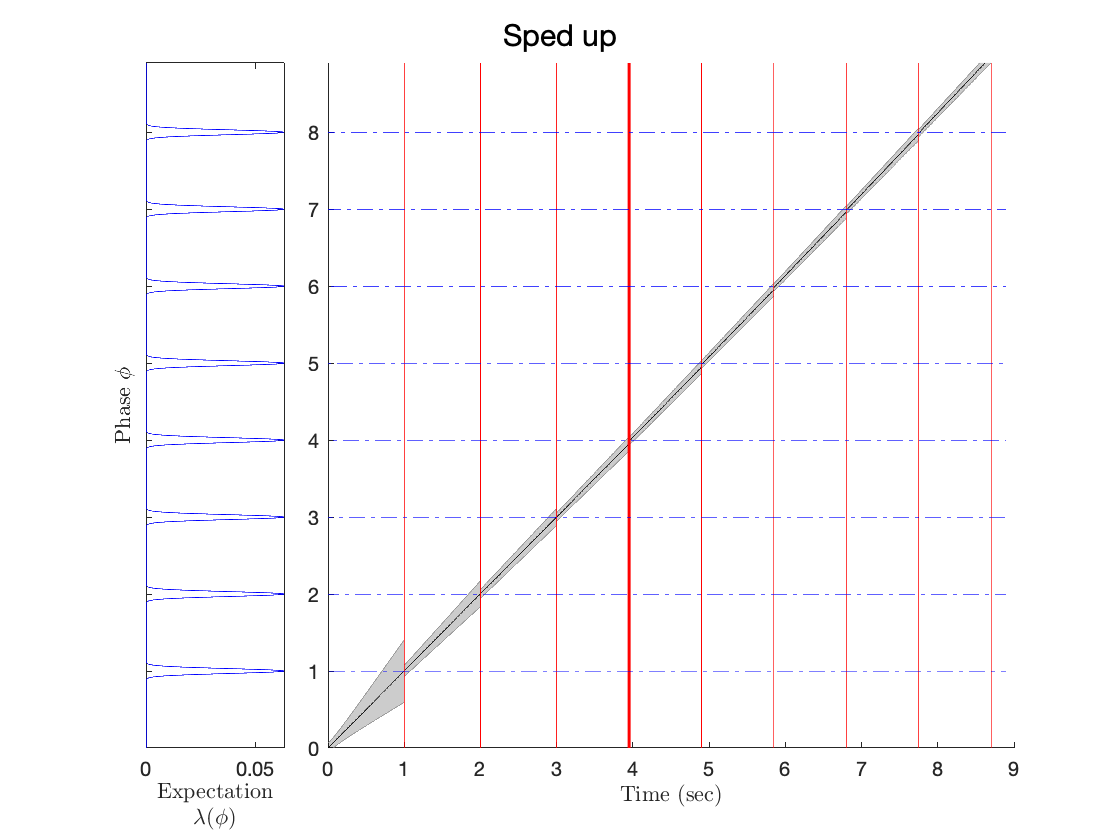

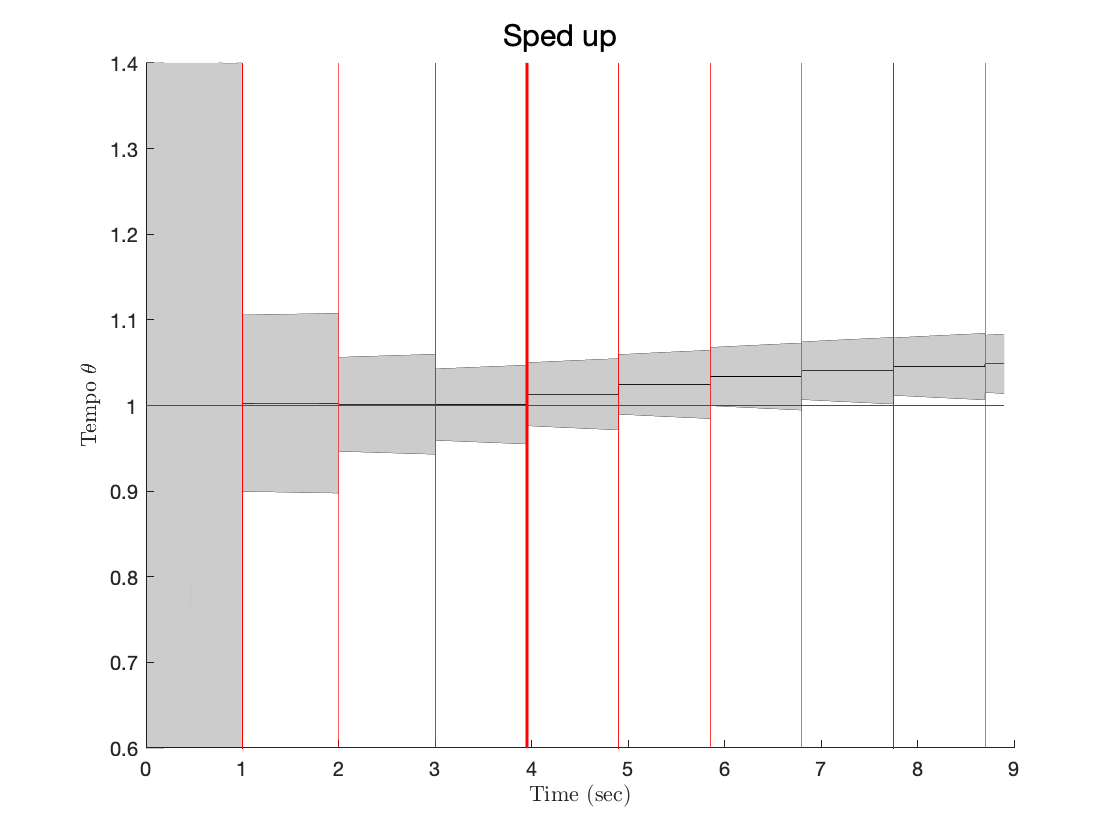

true_tempo = 1;
period = 1/true_tempo;
delta = 0.05;

ET = period:period:9*period;
ET_speed = ET;
ET_slow = ET;

ET_speed(3:end)=ET_speed(3) + (0 : period - delta: 6*(period - delta));
ET_slow(3:end)=ET_slow(3) + (0 : period + delta: 6*(period + delta));

lu = .005;
hei = ones(size(ET));
hei(4) = 2;

sigma_theta = .01;
sigma_phi = .02;

params = PATIPPET_params(...
    'means_unit', [1],...
    'expected_cycles',10,...
    'expected_period', 1,...
    'lambda_unit',lu,...
    'sigma_phi', sigma_phi,...
    'sigma_theta', sigma_theta,...
    'true_speed', true_tempo,...
    'event_times', ET_speed,...%[.8, 1.6, 2.4, 3.2, 4.0],...
    'mu_0', [0, true_tempo],...
    'V_0', [.001,0; 0,.04],...
    'lambda_0', .0001,...
    'dt_ellipse',.25,...
    'title', 'Sped up',...
    'highlight_event_indices',hei,...
    'display_phase', true,...
    'display_tempo', true,...    
    'display_phasetempo', false);
[mu_list_speed, V_list_speed] = run_PATIPPET(params);

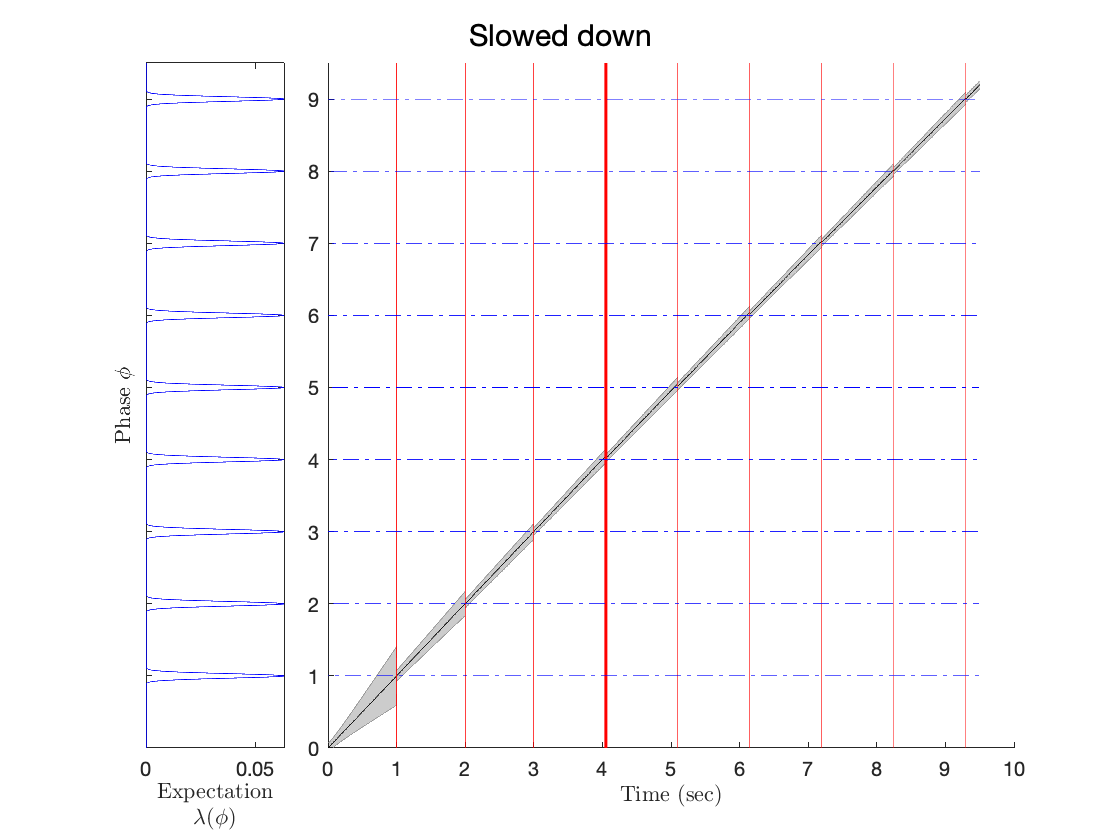

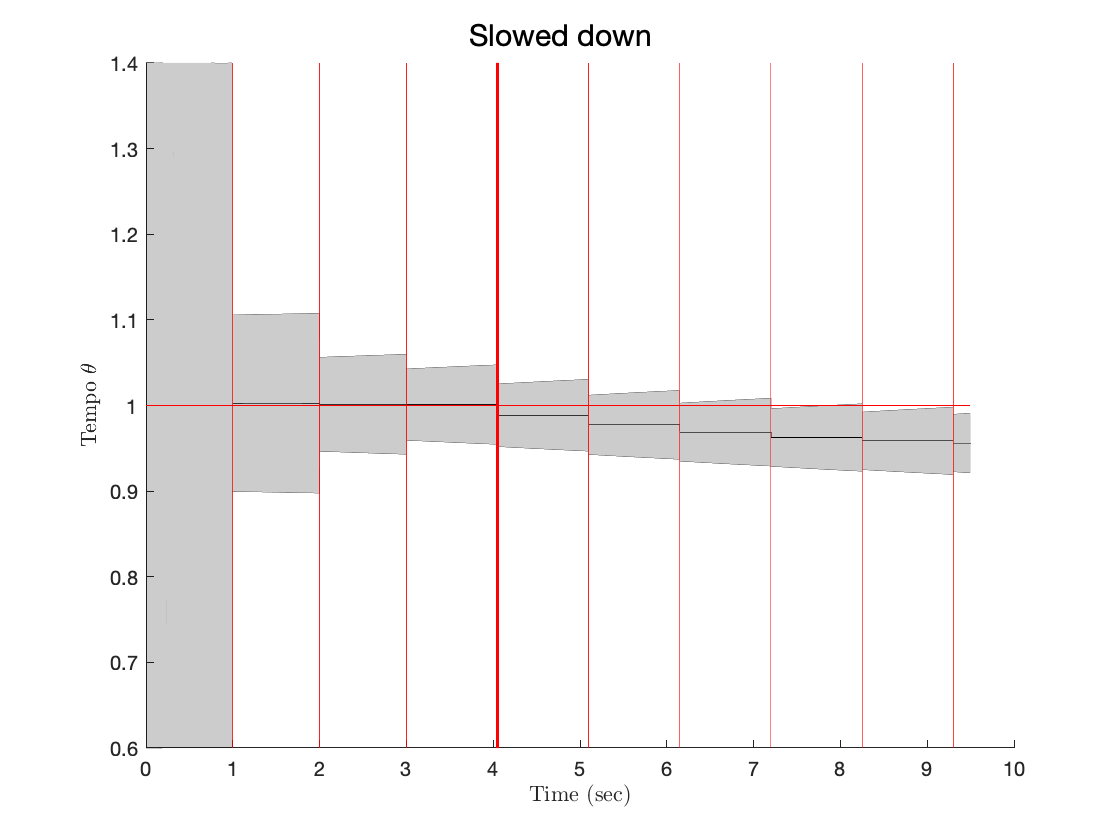


params = PATIPPET_params(...
    'means_unit', [1],...
    'expected_cycles',10,...
    'expected_period', 1,...
    'lambda_unit',lu,...
    'sigma_phi', sigma_phi,...
    'sigma_theta', sigma_theta,...
    'true_speed', true_tempo,...
    'event_times', ET_slow,...%[.8, 1.6, 2.4, 3.2, 4.0],...
    'mu_0', [0, true_tempo],...
    'V_0', [.001,0; 0,.04],...
    'lambda_0', .0001,...
    'dt_ellipse',.25,...
    'title', 'Slowed down',...
    'highlight_event_indices',hei,...
    'display_phase', true,...
    'display_tempo', true,...   
    'display_phasetempo', false);
[mu_list_slow, V_list_slow] = run_PATIPPET(params);


antitap_slow_list = [];
asynV_slow = [];
for i=2:size(mu_list_slow, 2);
    if floor(mu_list_slow(1, i) -.5)>floor(mu_list_slow(1, i-1) -.5)
        antitap_slow_list(end+1) = i*params.dt;
        asynV_slow(end+1) = i*params.dt + .5/mu_list_slow(2, i) - ET_slow(length(antitap_slow_list));
    end
end
ITI_slow = diff(antitap_slow_list)

ITI_slow =     0.9970    1.0010    1.0000    1.0410    1.0540    1.0570    1.0570    1.0560



antitap_speed_list = [];
asynV_speed = [];
for i=2:size(mu_list_speed, 2);
    if floor(mu_list_speed(1, i) -.5)>floor(mu_list_speed(1, i-1) -.5)
        antitap_speed_list(end+1) = i*params.dt;
        asynV_speed(end+1) = i*params.dt + .5/mu_list_speed(2, i) - ET_speed(length(antitap_speed_list));
    end
end
ITI_speed = diff(antitap_speed_list)

ITI_speed =     0.9970    1.0010    1.0000    0.9600    0.9470    0.9440    0.9430    0.9440


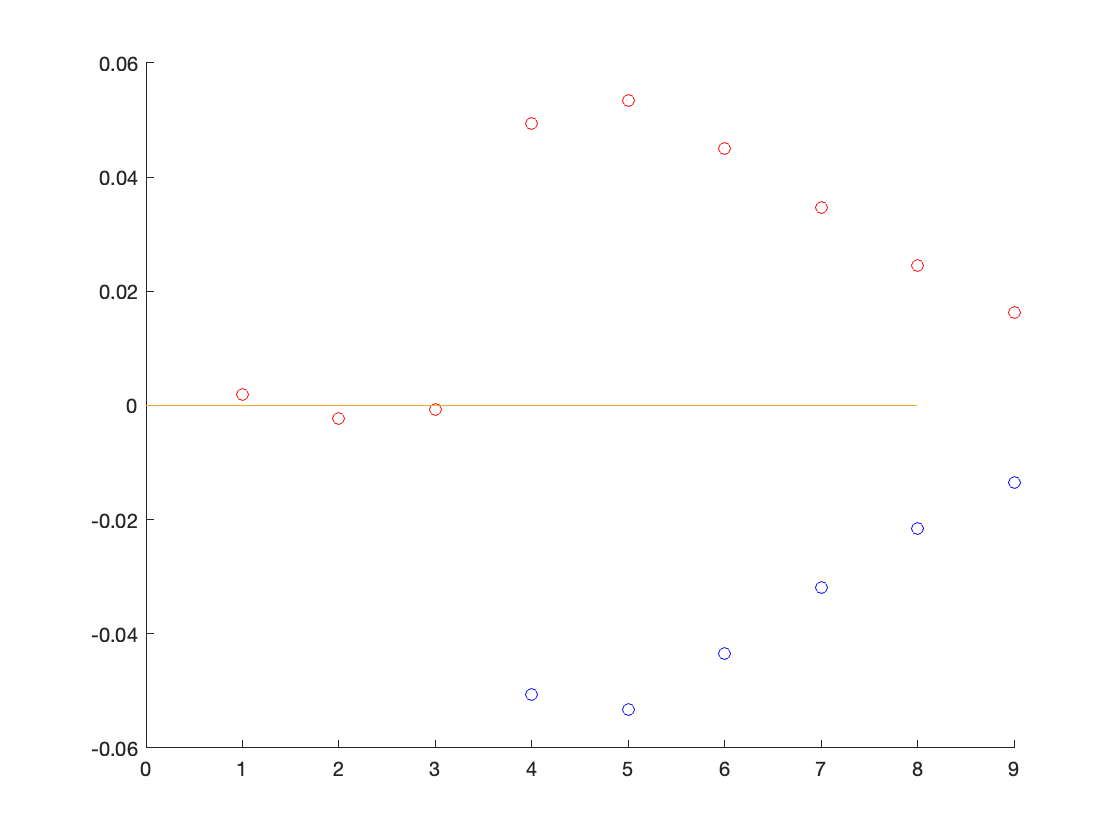


figure()
hold on
plot(asynV_slow, 'ob')
plot(asynV_speed, 'or')
plot([0, length(ITI_slow)], [0,0])

%plot([0, length(ITI_speed)], (period-delta)*[1,1])


## Comparing PATIPPET with and without theta correction

In second draft of manuscript, equations were updated such that events occurred dphi rather than dt -- thus, the rate of events within a given measure is the same regardless of tempo. One result was that tempo could be estimated from event rate when the event rate was constant. Here is PATIPPET's behavior with and without this correction.




params = PATIPPET_params(...
    'means_unit', [1],...
    'lambda_unit', [0],...
    'expected_cycles', 4,...
    'expected_period', 1,...
    'event_times', period:period:4*period,...%[.8, 1.6, 2.4, 3.2, 4.0],...
    'mu_0', [0, 1],...
    'V_0', [.001,0; 0,.04],...
    'lambda_0', 1,...
    'dt_ellipse',.25,...
    'corrected', false,...
    'title', 'no correction');
[mu_list, V_list] = run_PATIPPET(params);

params = PATIPPET_params(...
    'means_unit', [1],...
    'lambda_unit', [0],...
    'expected_cycles', 4,...
    'expected_period', 1,...
    'event_times', period:period:4*period,...%[.8, 1.6, 2.4, 3.2, 4.0],...
    'mu_0', [0, 1],...
    'V_0', [.001,0; 0,.04],...
    'lambda_0', 1,...
    'dt_ellipse',.25,...
    'corrected', true,...
    'title', 'with correction');
[mu_list, V_list] = run_PATIPPET(params);

## Keith Doelling's task

true_tempo = 1.2;
period = 1/true_tempo;
cycles = 6;

event_times = period:period:cycles*period;
event_times = event_times + .1*randn(size(event_times));

params = PIPPET_params(...
    'means_unit', [1],...
    'variance_unit',[.000001],...
    'expected_cycles', 8,...
    'expected_period', 1,...%'true_speed', true_tempo,...
    'event_times', event_times,...%[.8, 1.6, 2.4, 3.2, 4.0],...
    'mu_0', 0,...%[0, 1],...
    'V_0', [.001],...%,0; 0,.04],...
    'lambda_0', 0,...
    'sigma_phi',.1,...%'V_2',0.001,...
    'title', 'PIPPET'...
    );
[mu_list, V_list] = run_PIPPET(params);


params = PATIPPET_params(...
    'means_unit', [1],...
    'variance_unit',[.0001],...
    'expected_cycles', cycles,...
    'expected_period', 1,...
    'true_speed', true_tempo,...
    'event_times', event_times,...%[.8, 1.6, 2.4, 3.2, 4.0],...
    'mu_0', [0, 1],...
    'V_0', [.001,0; 0,.04],...
    'lambda_0', 0,...
    'sigma_phi',0.05,...
    'sigma_theta',0.02,...
    'title', 'High precision', ...
    'display_phase', true,...
    'display_tempo', true,...   
    'display_phasetempo', false);
[mu_list, V_list] = run_PATIPPET(params);


params = PATIPPET_params(...
    'means_unit', [1],...
    'variance_unit',[.01],...
    'expected_cycles', cycles,...
    'expected_period', 1,...
    'true_speed', true_tempo,...
    'event_times', event_times,...%[.8, 1.6, 2.4, 3.2, 4.0],...
    'mu_0', [0, 1],...
    'V_0', [.001,0; 0,.04],...
    'lambda_0', 0,...
    'sigma_phi',0.05,...
    'sigma_theta',0.02,...
    'title', 'Low precision', ...
    'display_phase', true,...
    'display_tempo', true,...   
    'display_phasetempo', false);
[mu_list, V_list] = run_PATIPPET(params);


Time warping

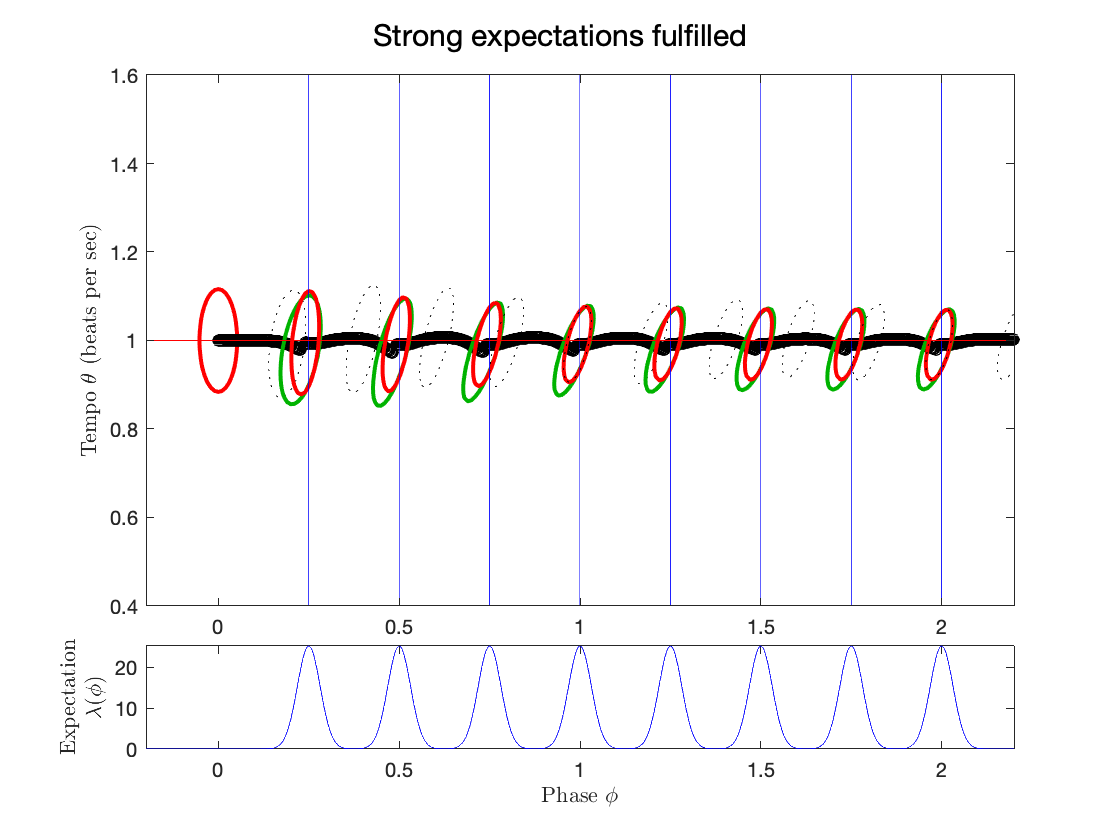

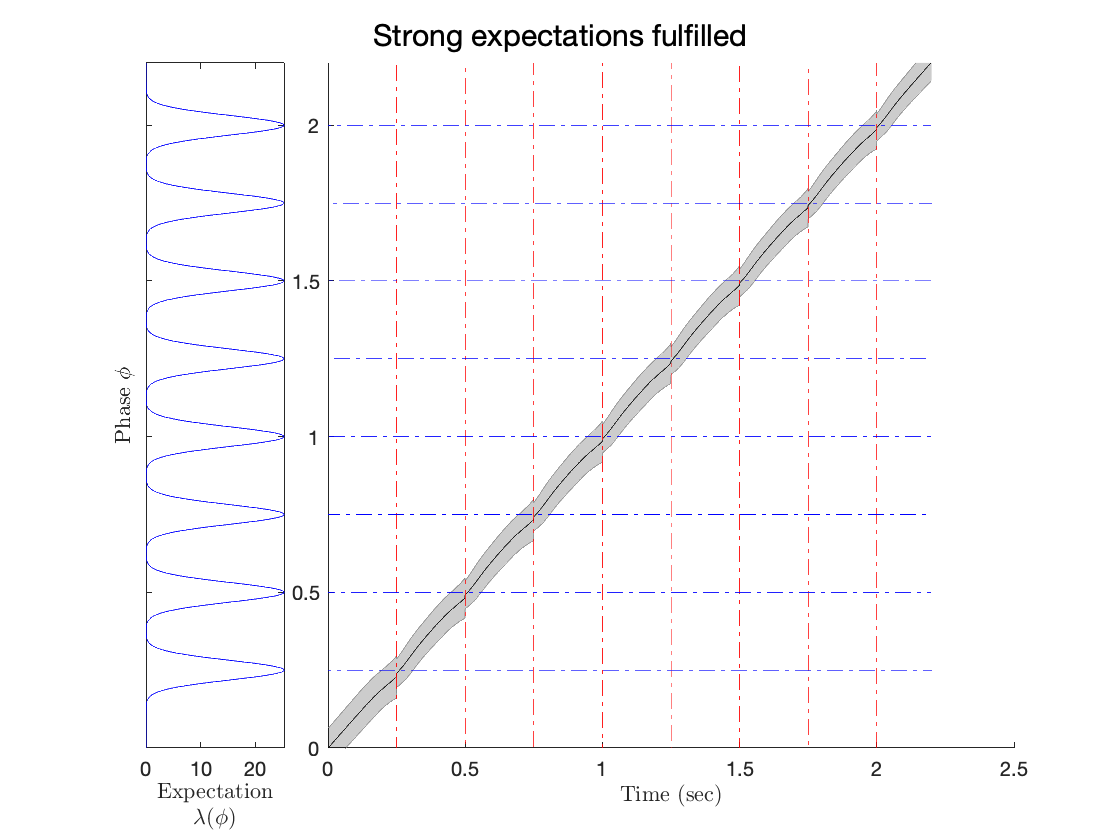



params = PATIPPET_params(...
    'dt', .001,...
    'expected_cycles', 8,...
    'lambda_unit', 100*0.02,...
    'sigma_phi', .015,...
    'sigma_theta', .06,...
    'V_0',[.001,0; 0,.005],...
    'event_times',[.25, .5,.75, 1, 1.25, 1.5,1.75, 2],...
    'title', 'Strong expectations fulfilled',...
    'display_phase', true);
[mu_list, V_list] = run_PATIPPET(params);

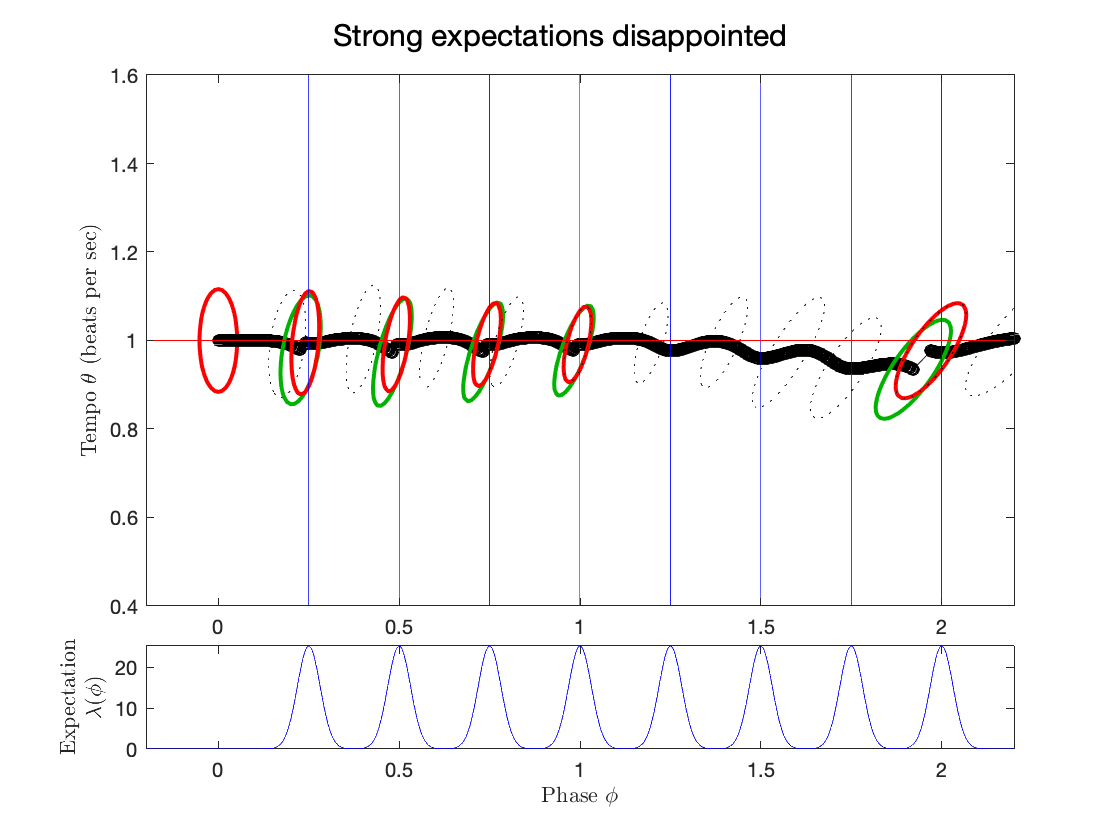

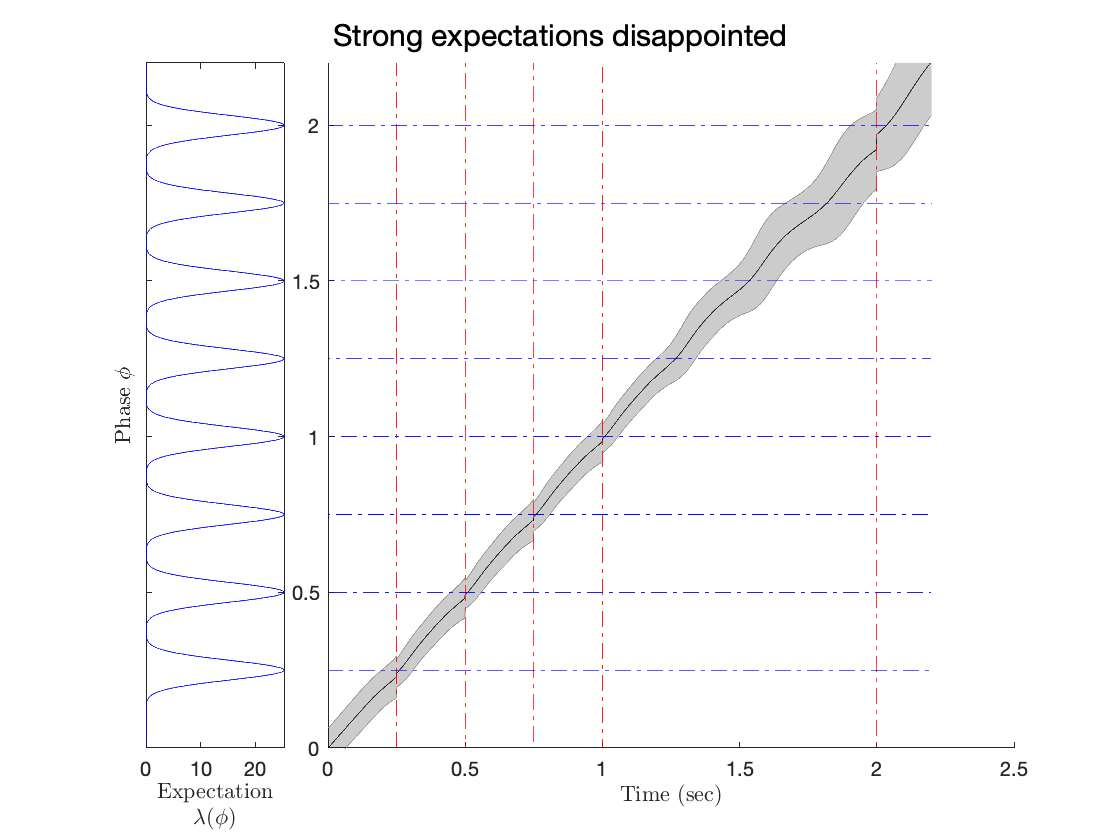


params2 = PATIPPET_params(...
    'dt', .001,...
    'expected_cycles', 8,...
    'lambda_unit', 100*0.02,...
    'sigma_phi', .015,...
    'sigma_theta', .06,...
    'V_0',[.001,0; 0,.005],...
    'event_times',[.25, .5,.75, 1, 2],...
    'title', 'Strong expectations disappointed',...
    'display_phase', true);
[mu_list, V_list] = run_PATIPPET(params2);

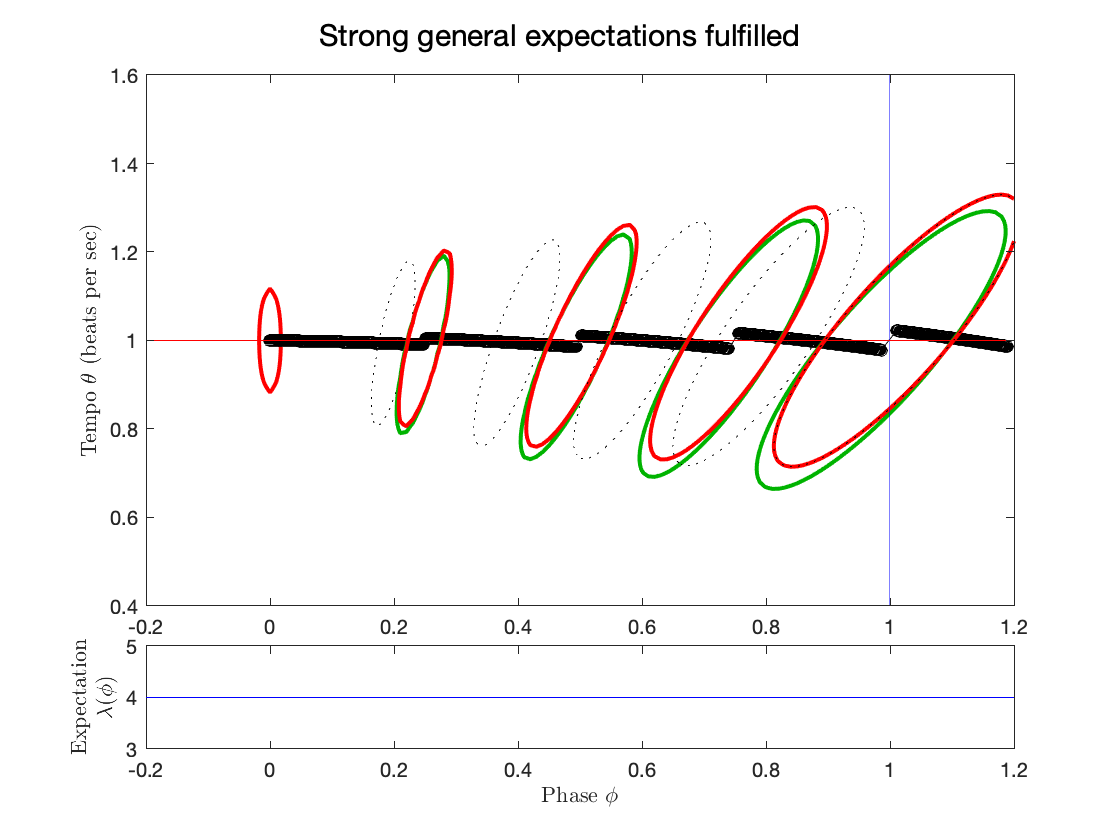

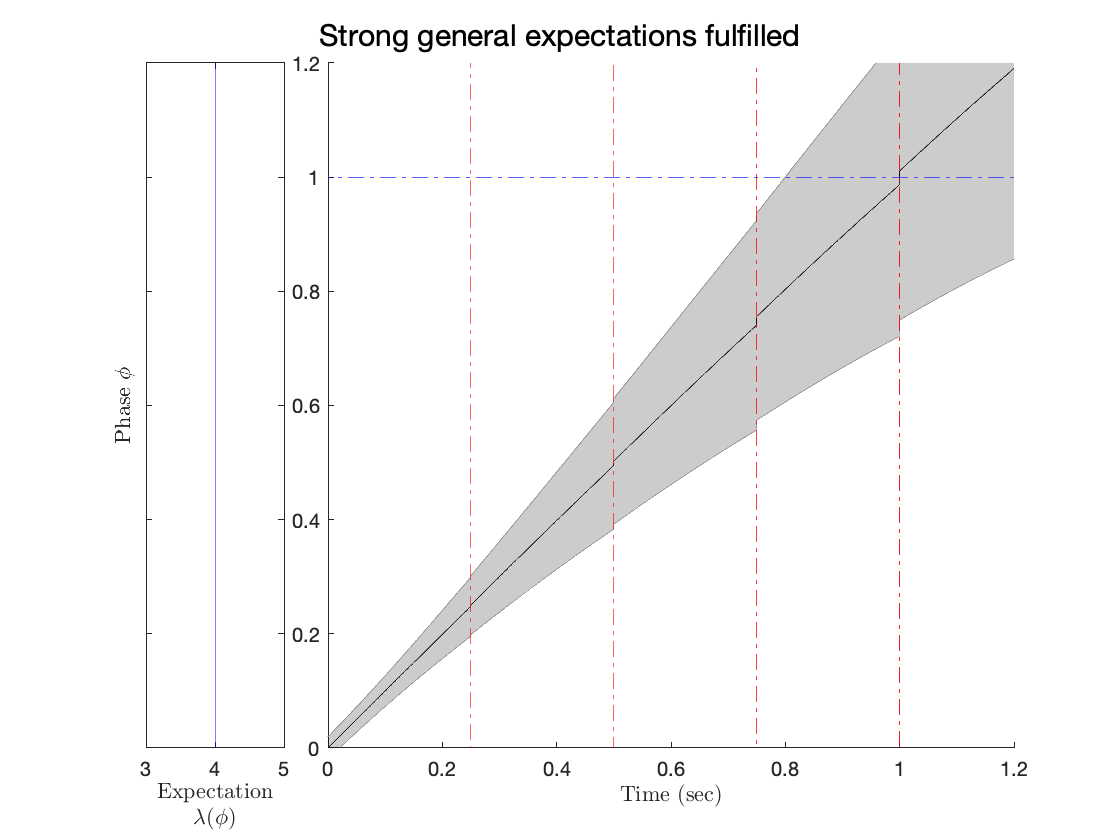

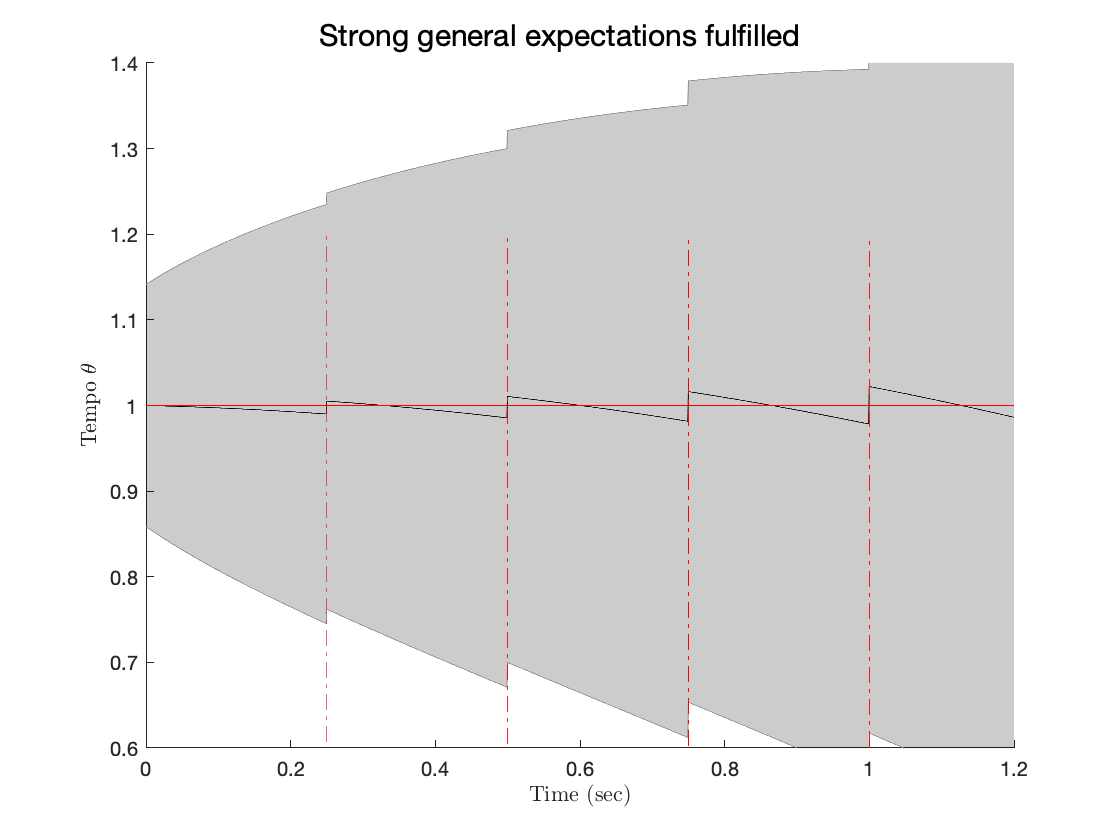

event_times = [.25, .5,.75, 1];

params = PATIPPET_params(...
    'dt', .001,...
    'expected_cycles', 1,...
    'expected_period', 1,...
    'means_unit', [1],...
    'lambda_unit', [0],...
    'variance_unit', [.0001],...
    'lambda_0', 4,...
    'sigma_phi', .015,...
    'sigma_theta', .2,...
    'V_0',[.0001,0; 0,.005],...
    'event_times',event_times,...
    'title', 'Strong general expectations fulfilled',...
    'display_tempo', true, ...
    'display_phase', true);
[mu_list, V_list] = run_PATIPPET(params);

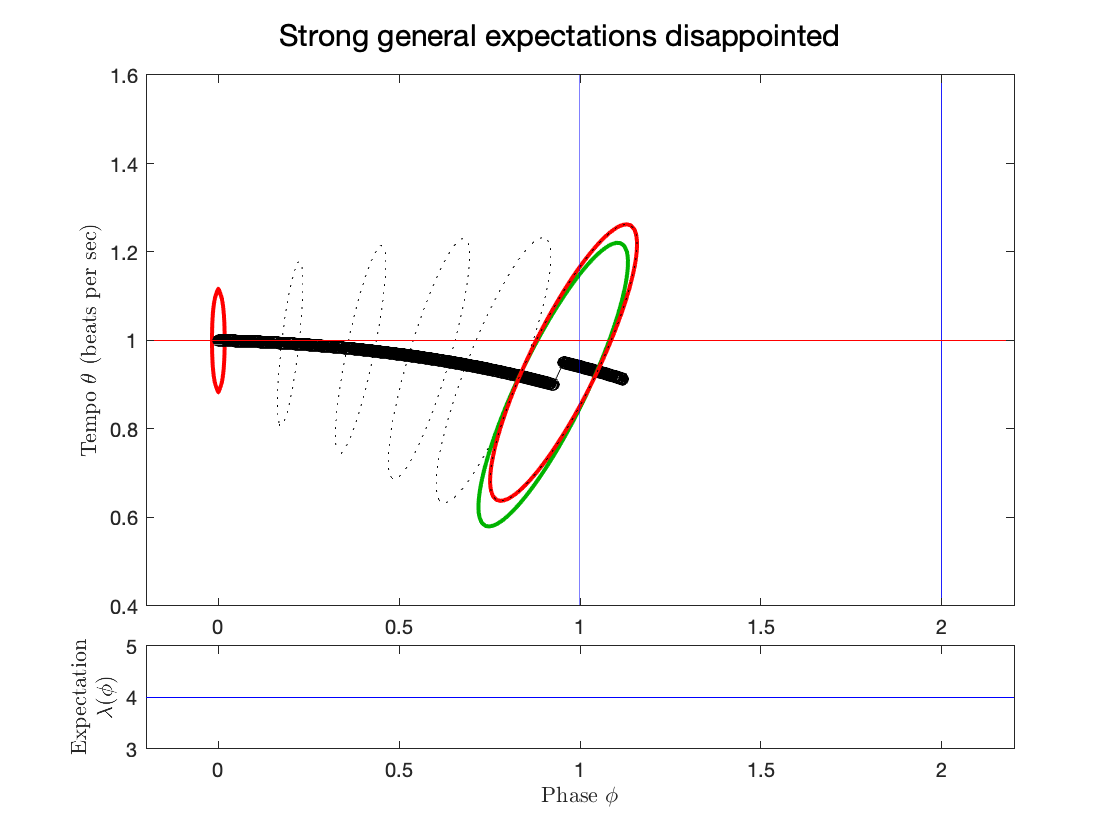

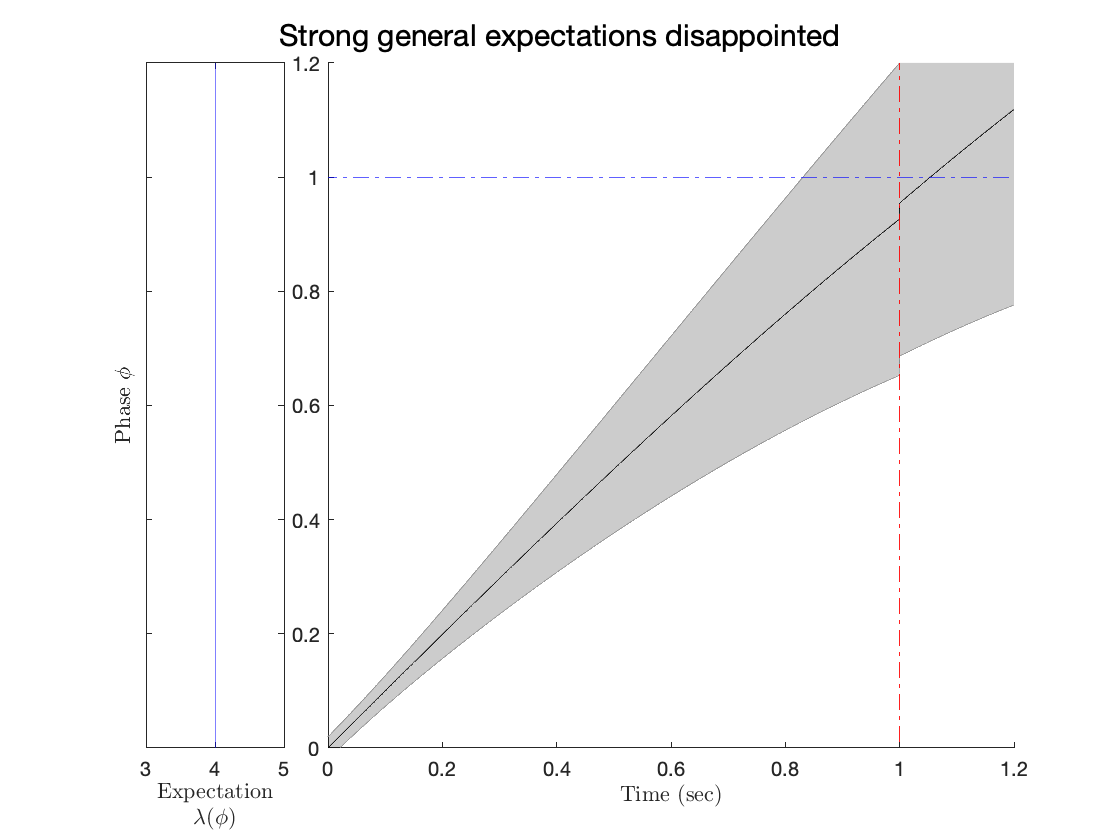

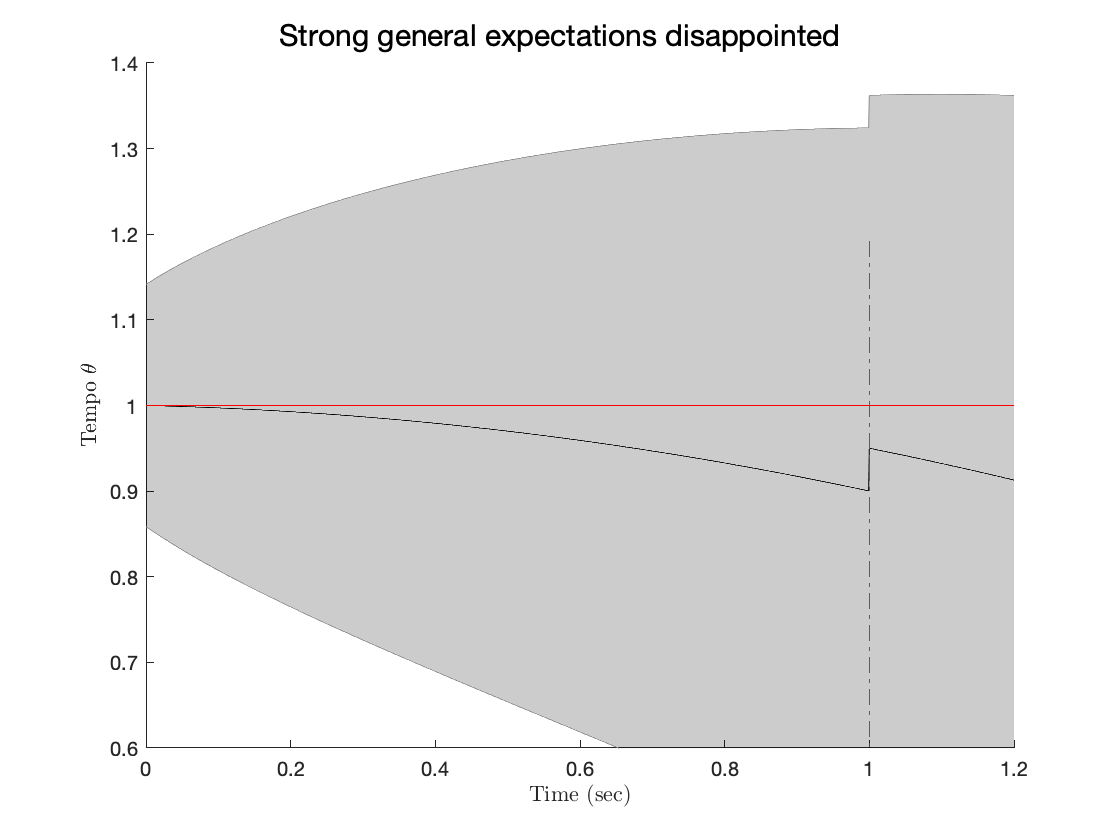


params = PATIPPET_params(...
    'dt', .001,...
    'expected_cycles', 2,...
    'expected_period', 1,...
    'means_unit', [1],...
    'lambda_unit', [0],...
    'variance_unit', [.0001],...
    'lambda_0', 4,...
    'sigma_phi', .015,...
    'sigma_theta', .2,...
    'V_0',[.0001,0; 0,.005],...
    'event_times',[1],...
    'title', 'Strong general expectations disappointed',...
    'display_tempo', true, ...
    'display_phase', true);
[mu_list, V_list] = run_PATIPPET(params);

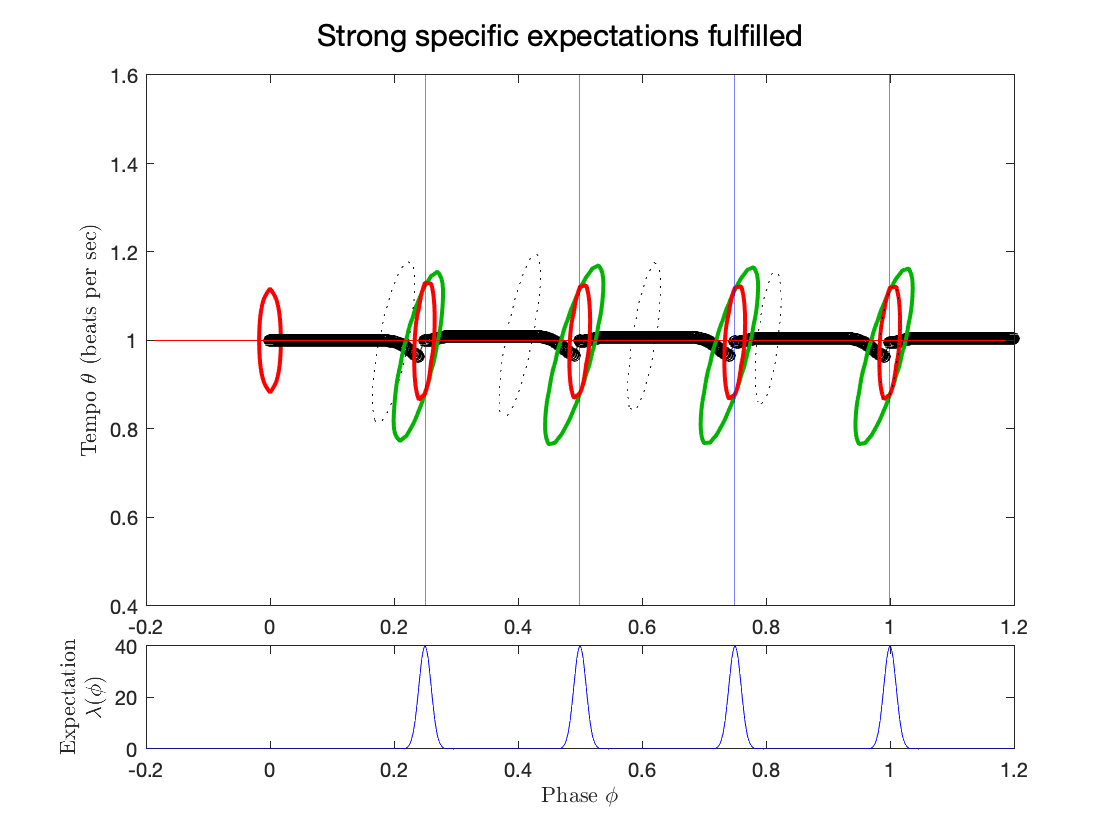

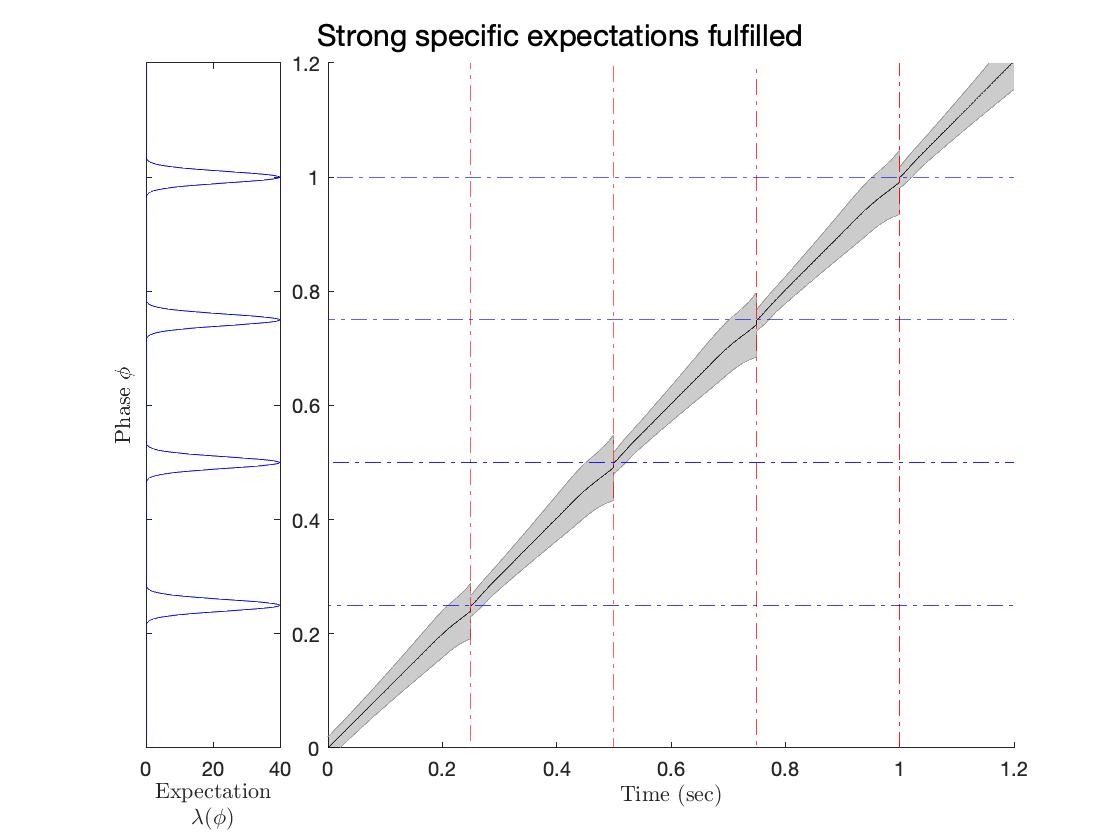

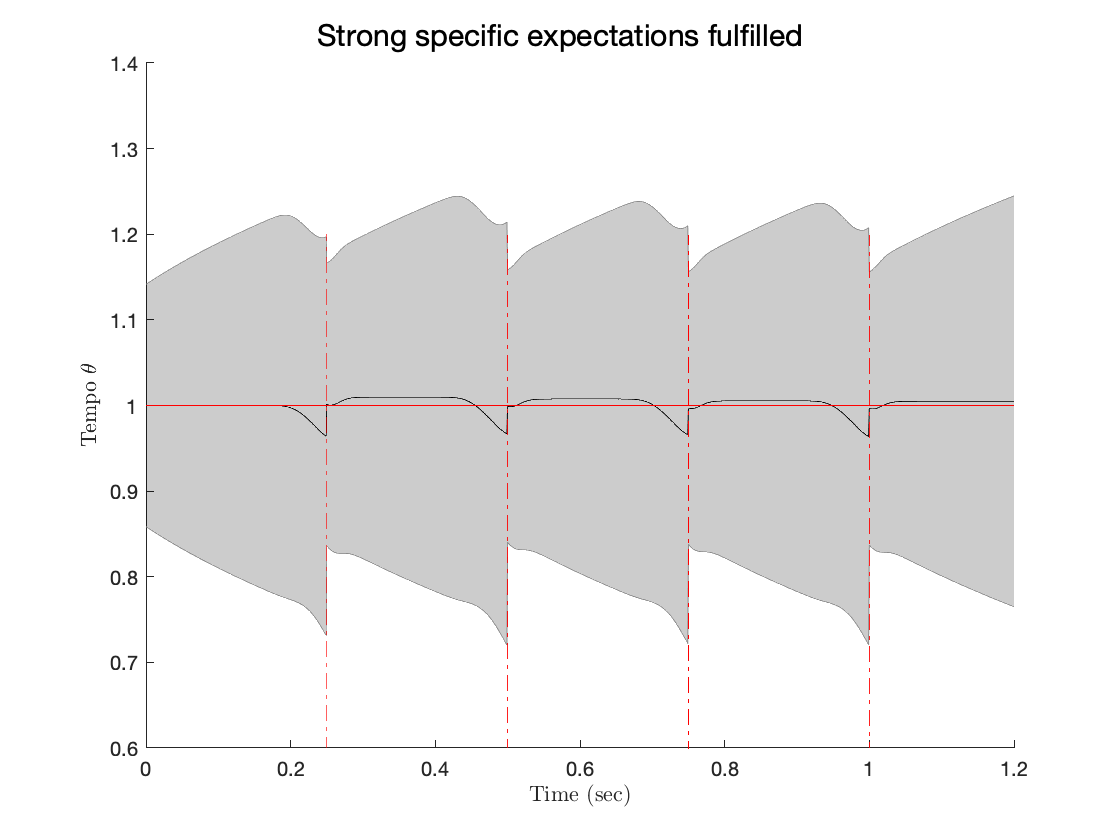


params2 = PATIPPET_params(...
    'dt', .001,...
    'expected_cycles', 4,...
    'expected_period', .25,...
    'means_unit', [.25],...
    'lambda_unit', [1],...
    'variance_unit', [.0001],...
    'lambda_0', .0001,...
    'sigma_phi', .015,...
    'sigma_theta', .2,...
    'V_0',[.0001,0; 0,.005],...
    'event_times',event_times,...
    'title', 'Strong specific expectations fulfilled',...
    'display_tempo', true, ...
    'display_phase', true);
[mu_list, V_list] = run_PATIPPET(params2);

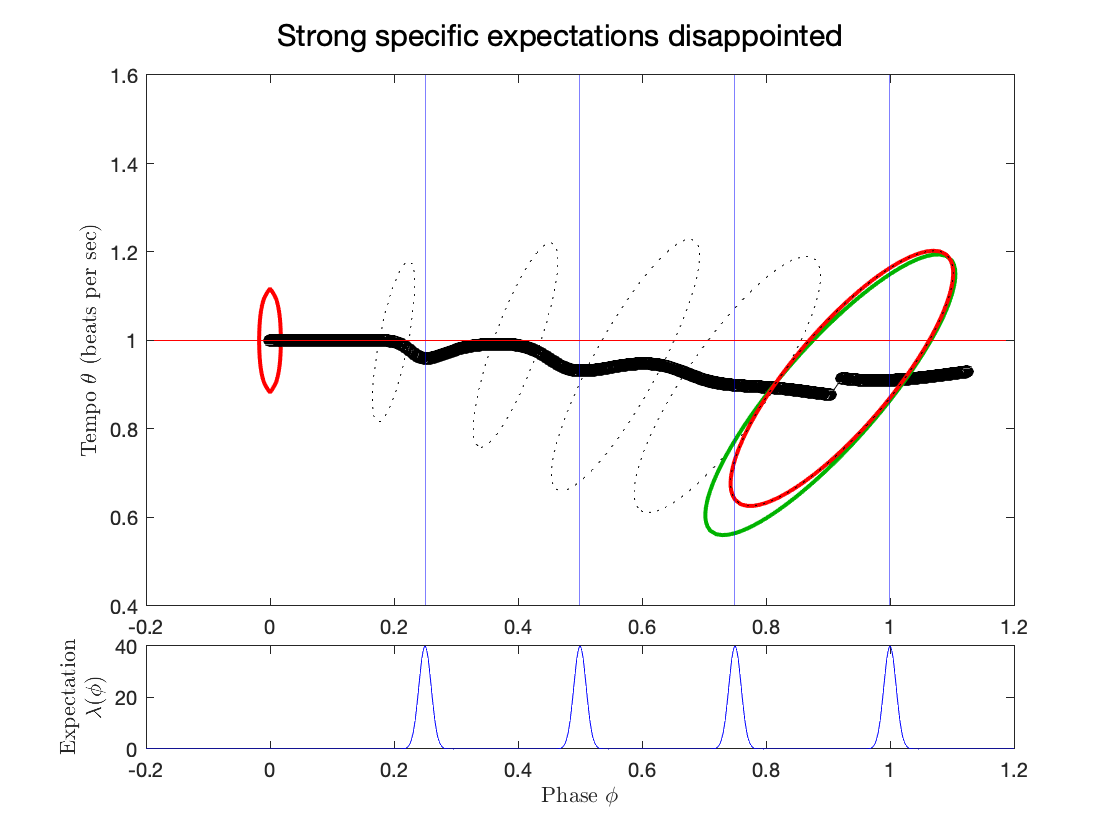

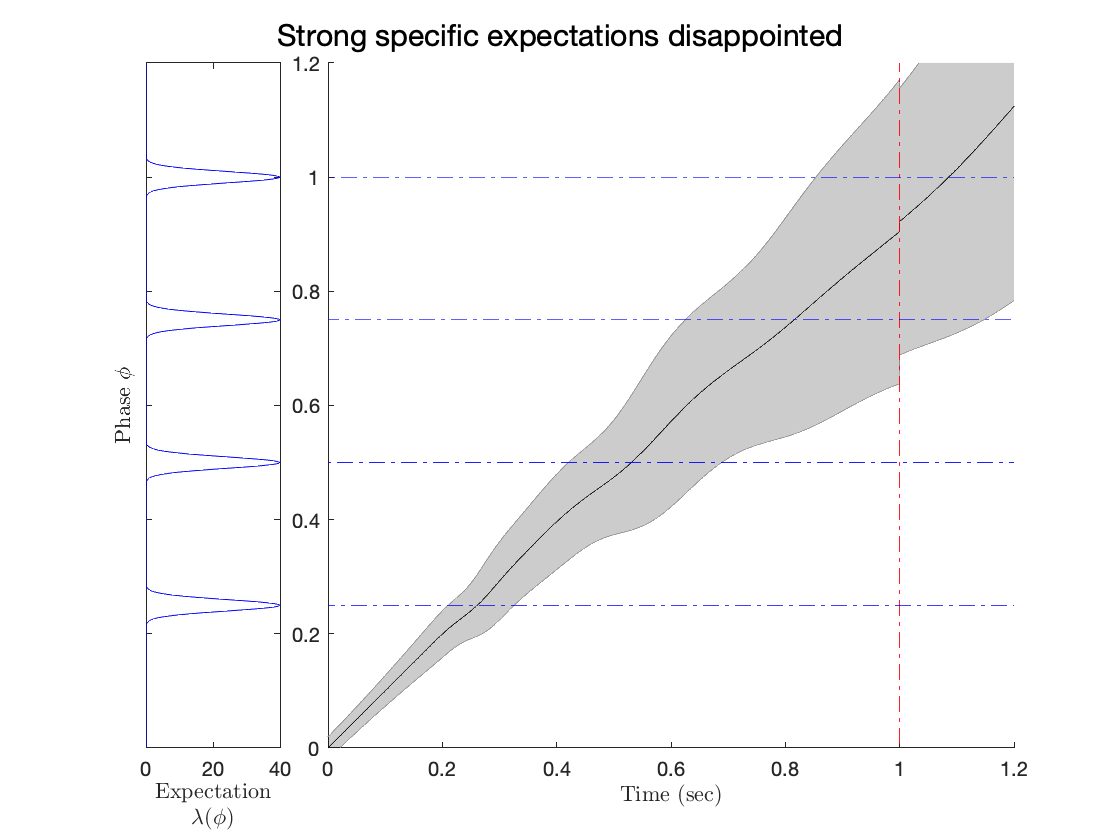

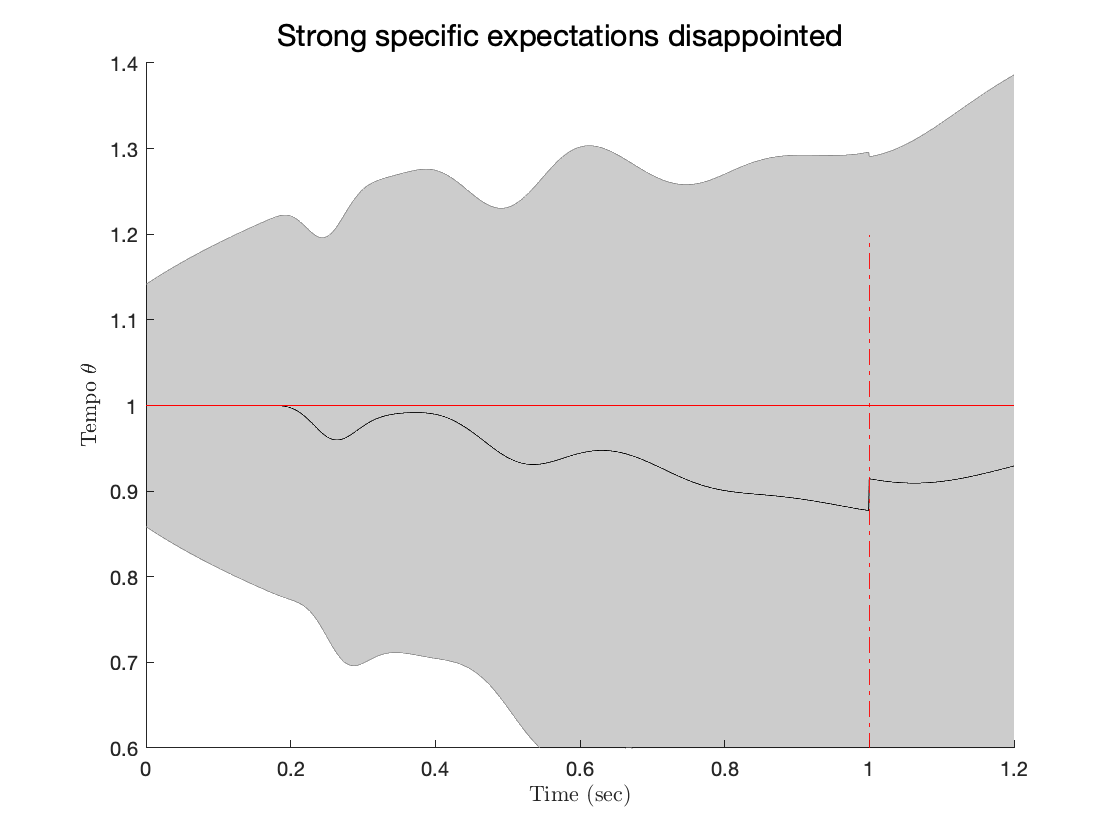



params2 = PATIPPET_params(...
    'dt', .001,...
    'expected_cycles', 4,...
    'expected_period', .25,...
    'means_unit', [.25],...
    'lambda_unit', [1],...
    'variance_unit', [.0001],...
    'lambda_0', .0001,...
    'sigma_phi', .015,...
    'sigma_theta', .2,...
    'V_0',[.0001,0; 0,.005],...
    'event_times',[1],...
    'title', 'Strong specific expectations disappointed',...
    'display_tempo', true, ...
    'display_phase', true);
[mu_list, V_list] = run_PATIPPET(params2);